# ECG processing and feature extraction

In this example we will use the signal enhancement operations in order to extract features from ECG signals. 

% Clear workspace and command window
clear;
clc;

## Introduction

ECGs record the electrical activity of a person's heart over a period of time. Physicians use ECGs to detect visually if a patient's heartbeat is normal or irregular. Atrial fibrillation (AFib) is a type of irregular heartbeat that occurs when the heart's upper chambers, the atria, beat out of coordination with the lower chambers, the ventricles. Usually, in AFib ECGs, the heart rate is not constant.

This example uses ECG data from the PhysioNet 2017 Challenge. 

The data consists of a set of ECG signals sampled at 300 Hz, divided into two classes:

- Normal (N)

- Atrial fibrillation (A)

More information about the Physionet challenge can be found [here](https://physionet.org/content/challenge-2017/1.0.0/).

This example performs some pre-processing operation to the ECG signal and finds the peaks in order to calculate heart rate and the variance between peaks. 

### Download the ECG data

You will use the the PhysioNet 2017 Challenge dataset (~100 MB). The operations to download and prepare the dataset will take a few minutes. You only need to do these operations once.

Download the PhysioNet 2017 Challenge dataset to the folder 'training2017'. Then collect the signals belonging to the classes 'Normal' and 'Arrhythmia', and save them in the 'PhysionetData.mat' file.

More information about the Physionet challenge can be found [here](https://physionet.org/content/challenge-2017/1.0.0/).

download_dataset();

### Load the ECG data

The loading operation adds two variables to the workspace:

- `signals` is a cell array that holds the ECG signals

- `labels` is a categorical array that holds the corresponding ground-truth labels of the signals.

data = load('PhysionetData.mat');
signals = data.Signals;
labels = data.Labels;
clear data;

### Select the signals

For sake of simplicity, this example focuses only on signals with 9000 samples.

L = cellfun(@length,signals); % L will contains the length of each signal in signals

% We select signals that have all the same length 
n = 9000;  % lenght of the selected signals
signals = signals(L==n);
labels  = labels(L==n);

fs = 300; % Sampling frequency, which is the same for all the signals
t = 1/fs .* (0:n-1);  % Sampling time

idN = find(labels == 'N'); % id of signals with Normal Rhythm 
idA = find(labels == 'A'); % id of signals with Atrial Fibrillation

signals = cell2mat(signals); % each row of signals is one ECG signal

### Plot of raw signal

First, let's show one ECG signal for both Normal Rhythm and Atrial Fibrillation. 

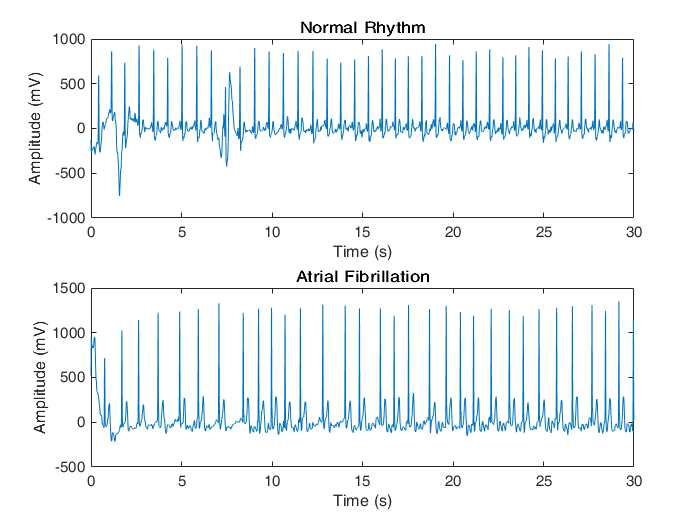

sel_a = 1; % selected Atrial Fibrillation signal to analyze
sel_n = 1; % selected Normal Rhythm signal to analyze

% Select the signal
signal_n = signals(idN(sel_n),:);
signal_a = signals(idA(sel_a),:);

%Plot the selected Normal Rhythm signal
figure();
subplot(2,1,1);
plot(t,signal_n);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Normal Rhythm');

%Plot the selected Atrial Fibrillation signal
subplot(2,1,2);
plot(t,signal_a);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Atrial Fibrillation')

### Plot the raw signal (zoom) 

Now we limit the plot to only 5 seconds (from the 10th second) to better see the wave details.

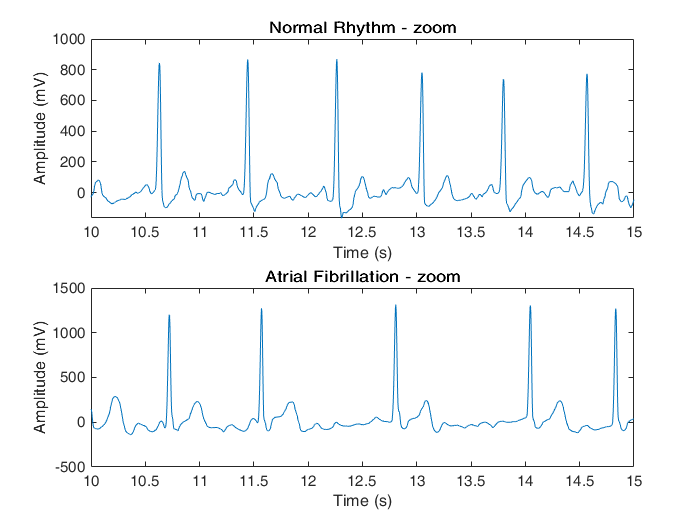

figure();

subplot(2,1,1);
plot(t,signal_n);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
xlim([10 15]);   
title('Normal Rhythm - zoom');

subplot(2,1,2);
plot(t,signal_a);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
xlim([10 15]);
title('Atrial Fibrillation - zoom')

### Plot of power spectrum

Next, let’s have a look at the power spectrum of the same ECG signals.

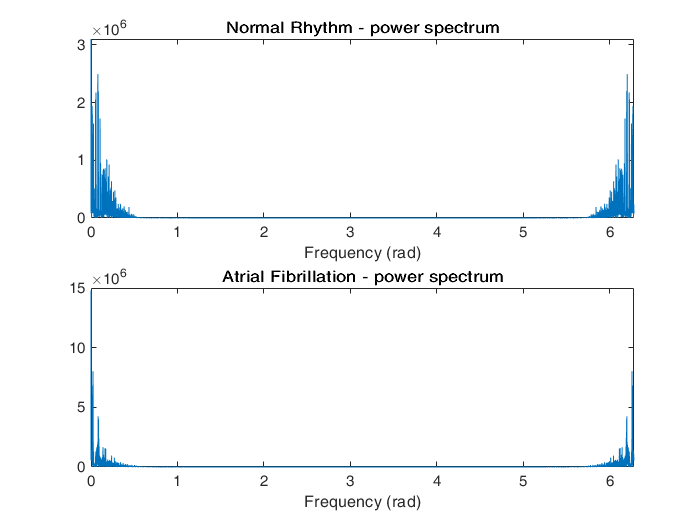

figure();

subplot(2,1,1);
f = linspace(0,2*pi,n); 
plot(f,abs( fft( signal_n ).^2 / n ));
title('Normal Rhythm - power spectrum');
xlabel('Frequency (rad)');
xlim([0 2*pi]);

subplot(2,1,2);
plot(f,abs( fft( signal_a ).^2 / n  ));
xlabel('Frequency (rad)');
title('Atrial Fibrillation - power spectrum')
xlim([0 2*pi]);

## Feature extraction

For the feature extraction phase, we exclude from the analysis the first and the last 5 seconds part of the signal since some of them present some acquisition problem. 

signals = signals(:,5*fs:25*fs); % Exlude the first and last 5 secondo from each signal

% now the signals have different lenghts so we redifine n, t and f
n = size(signals,2); 
t = 1/fs .* (0:n-1);
f = linspace(0,2*pi,n);

### Filter the signal

We perform a low-pass filter in order to de-noise the signal and a high-pass filter that will exclude very low frequency near the DC component of the Fourier transform. Then we normalize each signal to its maximum value.

% Filter the ECG signals
signals = signals';
signals = lowpass(signals, 0.06 );  % Low-pass filter
signals = highpass(signals,0.001);      % High-pass filter
signals = signals';
signals = signals ./ max(signals,[],2); % Normalze the signal

Let's show the results of the selected signals in time domain:

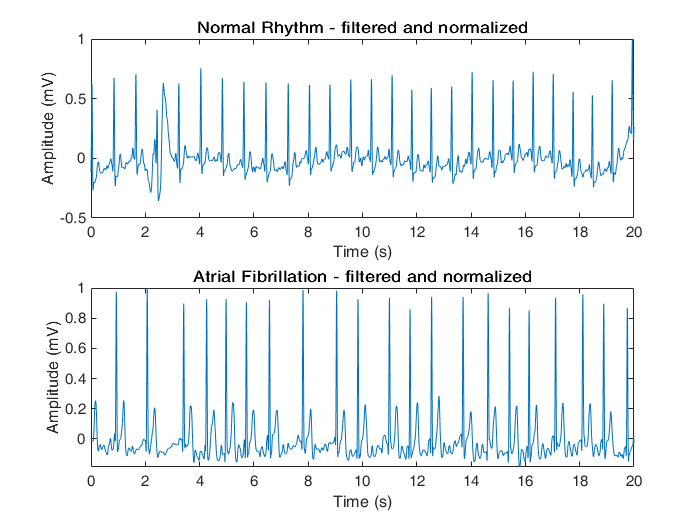

figure();

subplot(2,1,1);
plot(t,signals(idN(sel_n),:));
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Normal Rhythm - filtered and normalized');


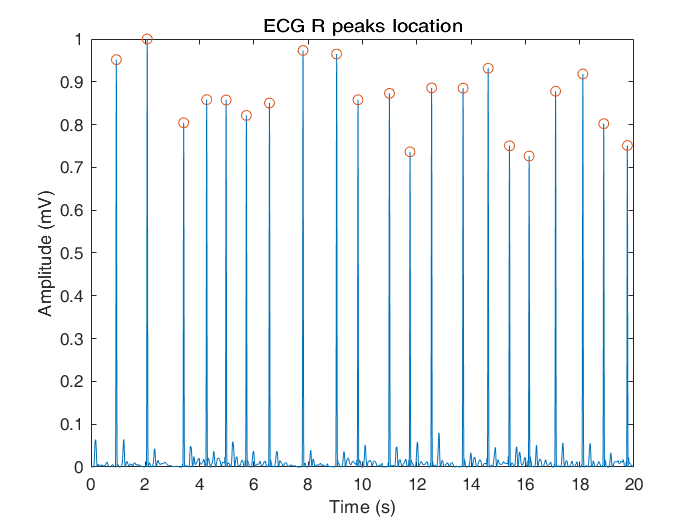

subplot(2,1,2);
plot(t,signals(idA(sel_a),:));
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Atrial Fibrillation - filtered and normalized')

### Find the heart beat

The function [`findpeaks`](https://it.mathworks.com/help/signal/ref/findpeaks.html) finds the local peaks of a given signal. `MinPeakHeight `specifies the minimum amplitude value for declaring a point as a peak, while` MinPeakDistance `discards peaks too close.

For each ECG we can estimate the heart rate has the mean time between the peaks. We calculate also the variance between the peaks as a feature of the ECG signal.

for i = 1 : size(signals,1)
    [pks,locs_R] = findpeaks(signals(i,:).^2,'MinPeakHeight',0.4,'MinPeakDistance',60); %R peaks
    mean_RR(i) = mean(diff(locs_R)/fs); % heart rate 
    var_RR(i) = var(diff(locs_R)/fs); % variance of heart rate
    
    if i == idA(sel_a) % show peaks only of the first selected normal rhythm signal
        figure();

Accuracy = 0.7242

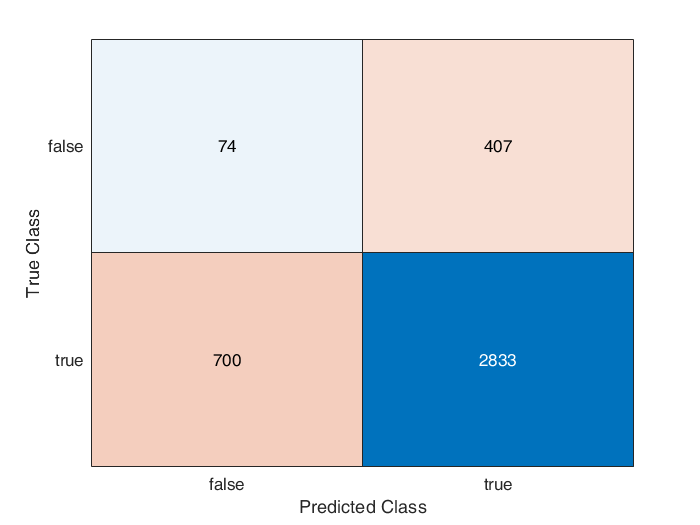

        plot(t,signals(i,:).^2);
        hold on;
        scatter(t(locs_R),pks);

        xlabel('Time (s)');
        ylabel('Amplitude (mV)');
        title('ECG R peaks location');        
    end
    
end

For some of the ECG, we cannot locate the peaks (resulting a nan value in the feature vector).

### Classify the ECG signal

Simply thresholding the RR peaks variance we classify the ECG signal as Normal Rhythm or Atrial Fibrillation one.

`The` [`confusionchart`](https://it.mathworks.com/help/stats/confusionchart.html) function is used to calculate the overall classification accuracy for the testing data predictions. 

% exlude the signals that have some errors
not_nan = not(isnan(var_RR)); 
labels_gt = labels(not_nan) == 'N';
mean_RR_sel = mean_RR(not_nan);
var_RR_sel = var_RR(not_nan);

% Calculate the accuracy of the prediction
Accuracy = sum ( labels_gt == (var_RR_sel < 0.9 )')./ numel(labels_gt)

figure();
confusionchart(labels_gt, (var_RR_sel < 0.9 )');

The accuracy of the prediction is very low since we are using a very simple feature.

## Further Practice

- Try to change the hyperparameter of the filter adopted and see the results.

- Find the errors (by visual inspection) in finding the ECG signal peaks and try to modify the parameters in order to solve as much as error you can.

## Further readings

- [cell2mat](https://it.mathworks.com/help/matlab/ref/cell2mat.html) 

- [isnan](https://it.mathworks.com/help/matlab/ref/isnan.html)

- [lowpass](https://it.mathworks.com/help/signal/ref/lowpass.html), [highpass](https://it.mathworks.com/help/signal/ref/highpass.html) and [bandpass](https://it.mathworks.com/help/signal/ref/bandpass.html)

- [findpeaks](https://it.mathworks.com/help/signal/ref/findpeaks.html)

## Helper functions

function download_dataset()
% This script parses the data from the PhysioNet 2017 Challenge and saves
% the data into PhysionetData.mat for quick and easy future use.

% Copyright 2017 The MathWorks, Inc.
file_url = 'https://physionet.org/files/challenge-2017/1.0.0/training2017.zip?download';
answer = input('Do you want to download the PhysioNet 2017 Challenge dataset?(Y,n): ', "s");
if strcmp(answer, 'Y')
    % Download and unzip the data, training2017.zip, from the PhysioNet website
    % https://physionet.org/challenge/2017/
    try
        fprintf('Downloading...');
        unzip(file_url);
        fprintf(' done.\n');
    catch ME
        fprintf('An error occurred during download. Please manually download the data from\nhttps://physionet.org/content/challenge-2017/1.0.0/training2017.zip');
    end
    
    
    % Navigate to the directory
    cd training2017
    
    % File with filenames and labels
    ref = 'REFERENCE.csv';
    
    % Create a table that contains the filenames and corresponding label data
    tbl = readtable(ref,'ReadVariableNames',false);
    tbl.Properties.VariableNames = {'Filename','Label'};
    
    % Delete 'Other Rhythm' and 'Noisy Recording' signals
    toDelete = strcmp(tbl.Label,'O') | strcmp(tbl.Label,'~');
    tbl(toDelete,:) = [];
    
    % Load each file in the table and store the corresponding signal data
    H = height(tbl);
    for ii = 1:H
        fileData = load([tbl.Filename{ii},'.mat']);
        tbl.Signal{ii} = fileData.val;
    end
    
    % Leave the training2017 directory
    cd ..
    
    % Format the data properly for LSTM training
    % Signals: Cell array of predictors
    % Labels: Categorical array of responses
    Signals = tbl.Signal;
    Labels = categorical(tbl.Label);
    
    % Save the variables to a MAT-file
    save PhysionetData.mat Signals Labels

end
if not(isfile('PhysionetData.mat'))
    fprintf('File "PhysionetData.mat" not found.\nEither download the file from %s\nor make sure you navigate to the directory where the Physionet data is saved.', file_url);
end
end
